# R_0 estimation 

In this code is find and calculated the value of the R_0 index. The method used to estimate is the one describe in Arino_2007 work. 

clc;
clear;
close all;
syms psi SC SA SH IC IA rho epsilon k3 k4 lambda3 lambda4 beta gamma A C SC0 SA0 SH0 
fig = 0;

To calculate the R0 the following matrices are defined:


Pi = [ rho, 1 0; 0, 0, 1];
D =  [ 1, 0, 0; 0, 1, 0; 0, 0, 1];
y =  [ SC; SH; SA];
b =  [ epsilon, 1];
x =  [ IC; IA];  
V = [  k4*A + lambda3 + gamma, -psi*k3*C - lambda4; 
      -k4*A - lambda3, psi * k3*C + gamma + lambda4 ];
y0= [SC0; SH0; SA0];


Definizione del R0

R_0(psi, rho, epsilon, k3, k4, lambda3, lambda4, beta, gamma, A, C, SC0, SA0, SH0) = beta .* b * inv(V) * Pi * D * y0

$$R\_0(psi, rho, epsilon, k3, k4, lambda3, lambda4, beta, gamma, A, C, SC0, SA0, SH0) = \begin{array}{l} {\mathrm{SA}}_{0}\,\left(\frac{\beta \,\left(\gamma +\lambda_{3}+A\,k_{4}\right)}{\sigma_{1}}+\frac{\beta \,\epsilon \,\left(\lambda_{4}+C\,k_{3}\,\psi \right)}{\sigma_{1}}\right)+{\mathrm{SH}}_{0}\,\left(\frac{\beta \,\left(\lambda_{3}+A\,k_{4}\right)}{\sigma_{1}}+\frac{\beta \,\epsilon \,\left(\gamma +\lambda_{4}+C\,k_{3}\,\psi \right)}{\sigma_{1}}\right)+{\mathrm{SC}}_{0}\,\rho \,\left(\frac{\beta \,\left(\lambda_{3}+A\,k_{4}\right)}{\sigma_{1}}+\frac{\beta \,\epsilon \,\left(\gamma +\lambda_{4}+C\,k_{3}\,\psi \right)}{\sigma_{1}}\right)\\ \mathrm{where}\\ \sigma_{1}=\gamma \,\lambda_{3}+\gamma \,\lambda_{4}+\gamma^{2}+A\,\gamma \,k_{4}+C\,\gamma \,k_{3}\,\psi \end{array}$$

Diamo dei valori ai parametri

rho1 = 0.65; % protezione da infezione
epsilon1 = 0.15; % gli IC che vanno a infettare in giro
k41 = 0.243; k31 = 0.48;
lambda41 = 0.143; lambda31 = 0.143;
gamma1 = 0.35; beta1 = 0.4;
A1 = 50/60e6; C1 = A1;
SC01 = 50/60e6; SA01 = 50/60e6; SH01 = 1-100/60e6;
psi = 0.5;

Figura della relazione livello di awareness - R0

psi = linspace(0,200); 

R0_val = R_0(psi, rho1, epsilon1, k31, k41, lambda31, lambda41, beta1, gamma1, A1, C1, SC01, SA01, SH01);
double(R0_val)

ans =     0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898    0.3898


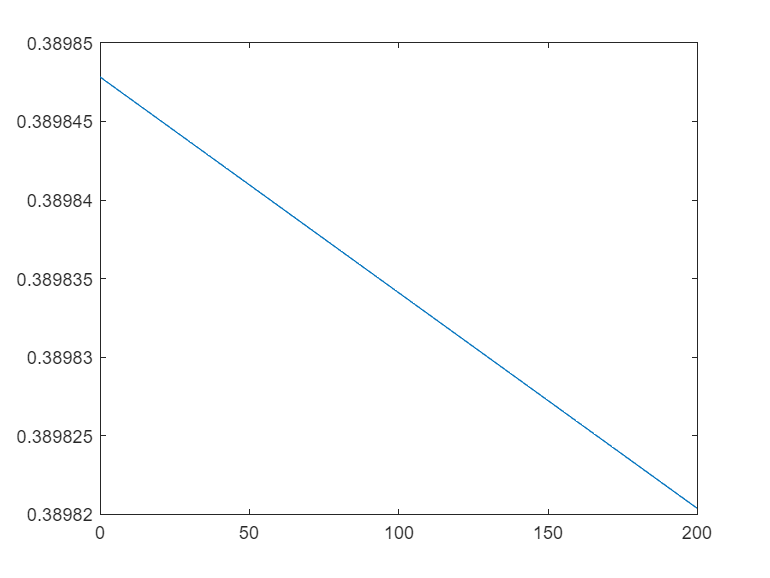


fig = fig+1;
figure(fig)
plot(psi, R_0(psi, rho1, epsilon1, k31, k41, lambda31, lambda41, beta1, gamma1, A1, C1, SC01, SA01, SH01))

SI osserva che (vedi anche note su quaderno) che essendo awareness moltiplicato per la popolazione di compliant e against all'inizio, se questi due gruppi sono molto piccoli trovo che R0 è identico a quello dovuto alla sola malattia.  Ovvio ma dimostrato ?

## Varying initial conditions

Multiple plots varying initial number of Compliant and Against, respectively the SC0 and SA0 variables. This change affect also the A and C groups. Several heatmaps are plotted using different awareness value.

SC0i = linspace(50/60e6,40e6/60e6,10); %interval from 50 to 10 milion 
SA0j = linspace(50/60e6,10e6/60e6,10); 
SA0j = linspace(50/60e6,50/60e6,10); 
psi = linspace(0.5,10,10);
R0_initial_SC_and_SA = zeros(length(SC01),length(SA01), length(psi));
for i = 1:length(SC0i)
    for j = 1:length(SA0j)
        for k = 1: length(psi)
            SH01 = 1-SC0i(i)-SA0j(j);
            A1 = SA0j(j)+ 50/60e6 + 0;
            C1 = SC0i(i) + 50/60e6 + 0;

            % x1 = lambda31 + A1*k41;
            % x2 = lambda41 + awk(k) *C1*k31;
            % ratio1 = (gamma1+x1+epsilon1*x2)/(x1+x2+gamma1);
            % ratio2 = (x1+epsilon1*(x2+gamma1))/(x1+x2+gamma1);
            % somma = SA0j(j)*ratio1 + (SH01 + rho1*SC0i(i))*ratio2;
            R0_initial_SC_and_SA(i,j,k) = R_0(psi(k), rho1, epsilon1, k31, k41, lambda31, lambda41, beta1, gamma1, A1, C1, SC0i(i), SA0j(j), SH01);
        end
     end 
end
% filename = "R0_variandoSC_SA,.mat";
% save(filename, "R0_initial_SC_and_SA", '-v7.3');
% load("R0_variandoSC_SA,.mat")

Prossimi casi, plot funzione di awareness SC e C, SC,SA C e A  più egli altri coeeficienit, anche se solo roh e epsilon hannno un valore compartamentale. 

## Varying SC0 and SA0

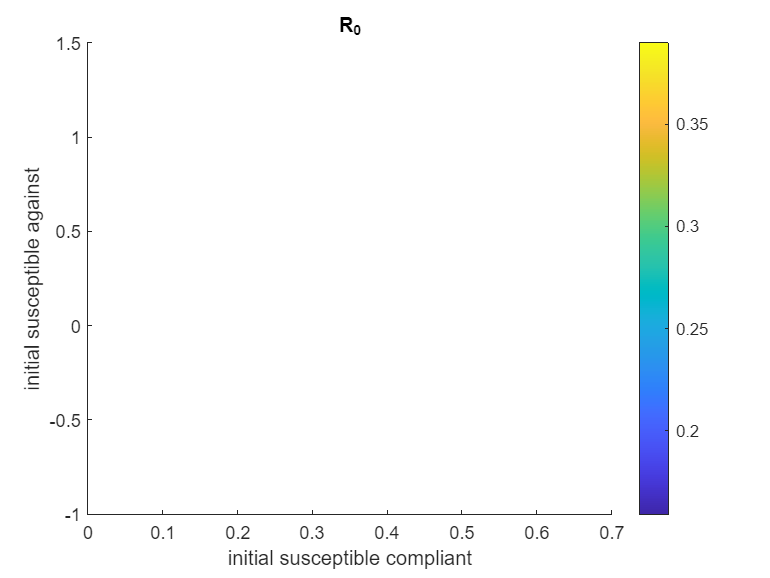


% SC0i = linspace(50/60e6,10e6/60e6); %interval from 50 to 10 milion 
% SA0j = linspace(50/60e6,10e6/60e6); 
% awk = linspace(0.1,100,10);
%% Equilibrium plot of R1 and R2
fig = fig+1;
figure(fig)
%1,1
d1 = 10;
fig = fig+1;
figure(fig)

[xx, yy] = meshgrid(SC0i,SA0j);
aga = reshape(R0_initial_SC_and_SA(:,:,d1),10,10,[]);
zz = aga; zz = transpose(zz);
surface(xx,yy,zz, 'edgecolor','none')
colorbar;
colormap default;
txt3 = "R_0";
title(txt3)
xlabel('initial susceptible compliant') 
ylabel('initial susceptible against') 